In =      1     0     0
     0     1     0
     0     0     1


$$A = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{{X_{3}}^{2}\,c}{{X_{1}}^{2}\,m} & 0 & -\frac{2\,X_{3}\,c}{X_{1}\,m}\\ 0 & 0 & -\frac{R}{L} \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ 0\\ \frac{1}{L} \end{array}\right)$$

C =      1     0     0


$$X = \left(\begin{array}{ccc} s & -1 & 0\\ -\frac{{X_{3}}^{2}\,c}{{X_{1}}^{2}\,m} & s & \frac{2\,X_{3}\,c}{X_{1}\,m}\\ 0 & 0 & s+\frac{R}{L} \end{array}\right)$$

$$Y = \begin{array}{l} \left(\begin{array}{ccc} -\frac{{X_{1}}^{2}\,m\,s}{\sigma_{1}} & -\frac{{X_{1}}^{2}\,m}{\sigma_{1}} & \frac{2\,L\,X_{1}\,X_{3}\,c}{\sigma_{1}\,\left(R+L\,s\right)}\\ -\frac{{X_{3}}^{2}\,c}{\sigma_{1}} & -\frac{{X_{1}}^{2}\,m\,s}{\sigma_{1}} & \frac{2\,L\,X_{1}\,X_{3}\,c\,s}{\sigma_{1}\,\left(R+L\,s\right)}\\ 0 & 0 & \frac{L}{R+L\,s} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={X_{3}}^{2}\,c-{X_{1}}^{2}\,m\,s^{2} \end{array}$$

$$q1 = \frac{962361}{980}$$

$$ans = 980.0$$

$$q2 = -\frac{981}{350}$$

$$ans = -2.8$$

$$q3 = -100$$

$$ans = -100.0$$

$$q4 = 100$$

$$ans = 100.0$$

$$varq1 = \left(\begin{array}{cc} \frac{16360137}{19600} & \frac{22134303}{19600} \end{array}\right)$$

$$varq2 = \left(\begin{array}{cc} -3.22328571416437625885009765625 & -2.38242857158184051513671875 \end{array}\right)$$

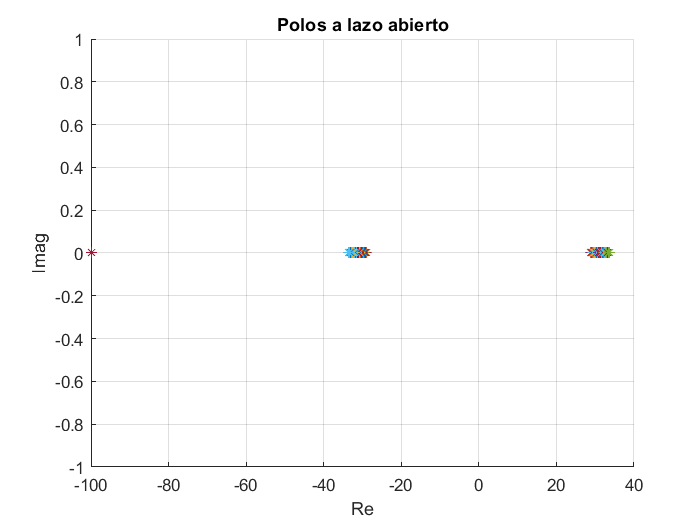

$$x1 = 930.0$$

$$y1 = -2.7$$

$$width = 98.0$$

$$height = 0.28$$

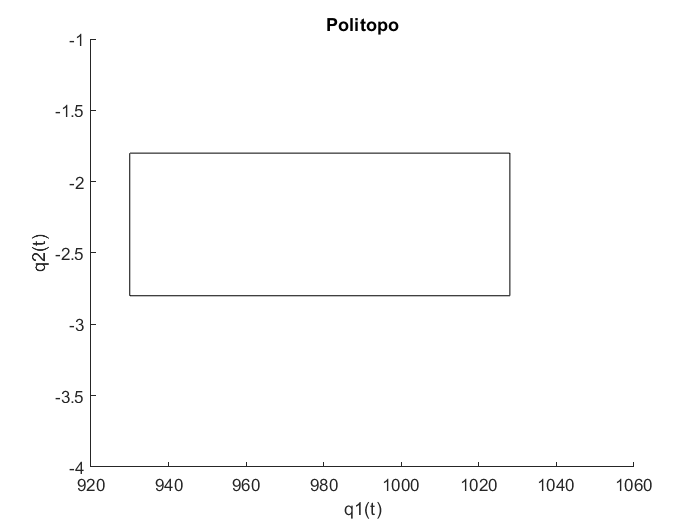

$$A1 = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{16360137}{19600} & 0 & -3.22328571416437625885009765625\\ 0 & 0 & -100 \end{array}\right)$$

$$A2 = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{16360137}{19600} & 0 & -2.38242857158184051513671875\\ 0 & 0 & -100 \end{array}\right)$$

$$A3 = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{22134303}{19600} & 0 & -3.22328571416437625885009765625\\ 0 & 0 & -100 \end{array}\right)$$

$$A4 = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{22134303}{19600} & 0 & -2.38242857158184051513671875\\ 0 & 0 & -100 \end{array}\right)$$


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.122587
     2                        0.016653
***                 new lower bound:    -0.078347
     3                        0.015746
     4                        0.014905
     5                    8.488472e-03
***                 new lower bound: -2.381637e-03
     6                    2.008717e-03
***                 new lower bound: -9.964065e-04
     7                    3.704465e-04
***                 new lower bound: -4.608605e-04
     8                    7.544091e-05
***                 new lower bound: -7.131480e-05
     9                    4.791895e-05
    10                    4.791895e-05
***                 new lower bound: -1.166467e-05
    11                    5.085297e-06
    12                    5.085297e-06
***          

K =     2.0704    0.0155    0.9408


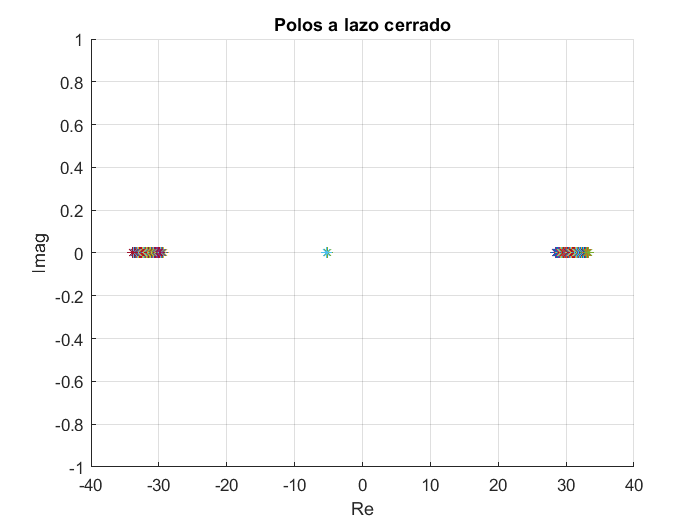

% definimos la variable compleja s
syms s c m R g L V x1 x2 x3 X1 X2 X3 % X mayuscula es para el punto de equilibrio; c = constante; m = masa ; R = resistencia; L = inductancia; V = tensión; g = gravedad
% In
In =  [1 0 0;0 1 0;0 0 1]
% A
A = [0 1 0; (c*X3^2)/(m*X1^2) 0 (-2*c*X3)/(m*X1);0 0 -R/L]
% B
B = [0;0;1/L]
% C 
C = [1 0 0]
% sIn - A 
X = s*In - A
% inversa 
Y = inv(X)



% Tomando como valores variables la masa y la resistencia y valores fijos
% la constante "c", la masa "M" y la tensión "V"

%q1 A(2,1) 
q1 =  (c*(V/R)^2)/(m*(((c*V^2)/(m*g*R^2)))^2);
%q2 A(2,3)
q2 = -1 * ((2*V/R*c)/(m*(c*V^2)/(m*g*R^2)));
%q3 A(3,3)
q3 = -R/L;
%q4 B(3,1)
q4 = 1/L;

% Sustituimos los valores por defecto 

q1 = subs(q1, [c V g m R], [0.0001, 7, 9.81 0.05 1])
vpa(q1, 2)
q2 = subs(q2, [c V g m R], [0.0001, 7, 9.81 0.05 1])
vpa(q2, 2)
q3 = subs(q3, [R L], [1 0.01])
vpa(q3, 2)
q4 = subs(q4, L, 0.01)
vpa(q4, 2)
% La variación en el tiempo de q1 y q2 en el tiempo sera de un 5% arriba y
% hacia abajo (definición del politopo)

%q1 pertenece a:

varq1 = [q1-q1*0.15 q1+q1*0.15]
varq2 = [vpa(q2+q2*0.15,2) vpa(q2-q2*0.15,2)]

figure
for Q1=varq1(1):0.1:varq1(2)
    for Q2=varq2(1):1:varq2(2)
        A=[0 1 0; Q1 0 Q2; 0 0 q3];
        p=eig(A);
        hold on
        plot(real(p(1)),imag(p(1)),'*')
        plot(real(p(2)),imag(p(2)),'*')
        plot(real(p(3)), imag(p(3)), '*')
    end
end
grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo abierto')
hold off

x1 = vpa(q1-q1*0.05,2)
y1 = vpa(q2-(q2*0.05),2)
width = vpa(q1+q1*0.05-q1+q1*0.05,2)
height =  vpa(abs(q2+q2*0.05-q2+q2*0.05),2)
% Dibujamos el politopo 
figure
rectangle('Position', [930 -2.8 98 1])
title('Politopo')
xlabel('q1(t)')
ylabel('q2(t)')
axis([920 1060 -4 -1])


% Creamos la desigualdad lineal matricial 


% Realimentación de estado + reubicación de polos en región R(Alfa,Ro) 
% Theta = 0.

% Planta
A1=[0 1 0;varq1(1) 0 varq2(1); 0 0 q3]

A2=[0 1 0;varq1(1) 0 varq2(2); 0 0 q3]

A3=[0 1 0;varq1(2) 0 varq2(1); 0 0 q3]

A4=[0 1 0;varq1(2) 0 varq2(2); 0 0 q3]

B=[0; 0; q4];

% Especificaciones región reubicación de polos
Alfa=5;
Ro=4;

% Creación sistema LMI
setlmis([])

% Variables LMIs
S=lmivar(1,[3 1]); % S(3,3) simétrica, 3x3 porque A es de 3x3 
R=lmivar(2,[1 3]); % R(1,2) arbitraria, 1x3 porque B es de 1x3

% S > 0

lmiterm([-1 1 1 S],1,1);

% Restricciones asociadas al parámetro Alfa

% 𝑨𝟏𝑺 + 𝑺𝑨𝟏𝑻 + 𝑩𝑹 + 𝑹𝑩 + 𝟐𝜶𝑺 < 𝟎
lmiterm([2 1 1 S],A1,1,'s');
lmiterm([2 1 1 R],B,1,'s');
lmiterm([2 1 1 S],2*Alfa,1);

% 𝑨𝟐𝑺 + 𝑺𝑨𝟐𝑻 + 𝑩𝑹 + 𝑹𝑩 + 𝟐𝜶𝑺 < 𝟎
lmiterm([3 1 1 S],A2,1,'s');
lmiterm([3 1 1 R],B,1,'s');
lmiterm([3 1 1 S],2*Alfa,1);

% 𝑨𝟑𝑺 + 𝑺𝑨𝟑𝑻 + 𝑩𝑹 + 𝑹𝑩 + 𝟐𝜶𝑺 < 𝟎
lmiterm([4 1 1 S],A3,1,'s');
lmiterm([4 1 1 R],B,1,'s');
lmiterm([4 1 1 S],2*Alfa,1);

% 𝑨𝟒𝑺 + 𝑺𝑨𝟒𝑻 + 𝑩𝑹 + 𝑹𝑩 + 𝟐𝜶𝑺 < 𝟎
lmiterm([5 1 1 S],A4,1,'s');
lmiterm([5 1 1 R],B,1,'s');
lmiterm([5 1 1 S],2*Alfa,1);

% Restricciones asociadas al parámetro Ro

% (A1,B)
lmiterm([6 1 1 S],-Ro,1);
lmiterm([6 1 2 S],A1,1);
lmiterm([6 1 2 R],B,1);
lmiterm([6 2 2 S],-Ro,1);

% (A2,B)
lmiterm([7 1 1 S],-Ro,1);
lmiterm([7 1 2 S],A2,1);
lmiterm([7 1 2 R],B,1);
lmiterm([7 2 2 S],-Ro,1);

% (A3,B)
lmiterm([8 1 1 S],-Ro,1);
lmiterm([8 1 2 S],A3,1);
lmiterm([8 1 2 R],B,1);
lmiterm([8 2 2 S],-Ro,1);

% (A4,B)
lmiterm([9 1 1 S],-Ro,1);
lmiterm([9 1 2 S],A4,1);
lmiterm([9 1 2 R],B,1);
lmiterm([9 2 2 S],-Ro,1);


% Ejecución del solver
LMISYS=getlmis;
[tmin,xfeas]=feasp(LMISYS);

% Solución
S=dec2mat(LMISYS,xfeas,S);
R=dec2mat(LMISYS,xfeas,R);

K=R*inv(S)


% Polos a lazo cerrado del sistema  politópico

syms R
figure
for Q1=varq1(1):0.1:varq1(2)
    for Q2=varq2(1):1:varq2(2)
        A=[0 1 0; Q1 0 Q2; 0 0 q3];
        p=eig(A+B*K);
        hold on
        plot(real(p(1)),imag(p(1)),'*');
        plot(real(p(2)),imag(p(2)),'*');
        plot(real(p(3)), imag(p(3)), '*');
    end
end
grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo cerrado')
hold off